# Statistics for Engineering

## Author    : Hakkı Can Akut

### Description 

Analyzing Apple Mobility Trends Data https://www.apple.com/covid19/mobility and the covid data https://www.ecdc.europa.eu/en/publications-data/download-todays-data-geographicdistribution-covid-19-cases-worldwide in Matlab.

### Load Data

import COVID19geographicdisbtributionworldwide20200428.*;
import applemobilitytrends-2020-04-27.csv.*;
apple= applemobilitytrends20200427;
Covid19= COVID19geographicdisbtributionworldwide20200428;

**a) Is there a correlation between mobility trends and the number of new cases for countries (SPAIN, ENGLAND, GERMANY, TURKEY, USA, SWITZERLAND, EGYPT AND FRANCE)**

% March 1 to April 18 Spain
spainApple= sum(apple{125:127,end-57:end-9});
spainNewCases= Covid19.cases(11726:-1:11678)';
correlation_Spain=corr(spainNewCases',spainApple')

correlation_Spain = -0.7560

There is moderate negative correlation between mobility trends and the number of new cases for Spain.

% March 1 to April 18 England
englandApple= sum(apple{141:143,end-57:end-9});
englandNewCases= Covid19.cases(13012:-1:12964)';
correlation_England=corr(englandNewCases',englandApple')

correlation_England = -0.7393

There is moderate negative correlation between mobility trends and the number of new cases for England.

% March 1 to April 18 Germany
germanyApple= sum(apple{47:49,end-57:end-9});
germanyNewCases= Covid19.cases(4908:-1:4860)';
correlation_Germany=corr(germanyNewCases',germanyApple')

correlation_Germany = -0.7964

There is moderate negative correlation between mobility trends and the number of new cases for Germany.

% March 16 to April 18 Turkey(started from march 16 because lack of data)
turkeyApple= sum(apple{139:140,end-42:end-9});
turkeyNewCases= Covid19.cases(12718:-1:12685)';
correlation_Turkey=corr(turkeyNewCases',turkeyApple')

correlation_Turkey = -0.6418

There is moderate negative correlation between mobility trends and the number of new cases for Turkey.

% March 1 to April 18 USA
usaApple= sum(apple{148:150,end-57:end-9});
usaNewCases= Covid19.cases(13175:-1:13127)';
correlation_USA=corr(usaNewCases',usaApple')

correlation_USA = -0.7477

There is moderate negative correlation between mobility trends and the number of new cases for USA.

% March 1 to April 18 Switzerland
switzerlandApple= sum(apple{131:133,end-57:end-9});
switzerlandNewCases= Covid19.cases(12163:-1:12115)';
correlation_Switzerland=corr(switzerlandNewCases',switzerlandApple')

correlation_Switzerland = -0.8223

There is strong negative correlation between mobility trends and the number of new cases for Switzerland.

% March 6 to April 18 Egypt(started from march 6 because lack of data)
egyptApple= sum(apple{36:37,end-51:end-9});
egyptNewCases= Covid19.cases(3869:-1:3827)';
correlation_Egypt=corr(egyptNewCases',egyptApple')

correlation_Egypt = -0.3449

There is weak negative correlation between mobility trends and the number of new cases for Egypt.

% March 1 to April 18 France
franceApple= sum(apple{44:46,end-57:end-9});
franceNewCases= Covid19.cases(4542:-1:4494)';
correlation_France=corr(franceNewCases',franceApple')

correlation_France = -0.7099

There is moderate negative correlation between mobility trends and the number of new cases for France.

To sum up, the most negative correlation is for Switzerland(-0.8223) and the less one is for Egypt(-0.3449).

**b)** **Is there a time lag between the mobility trends and the number of new cases for TURKEY, ENGLAND and GREECE?**

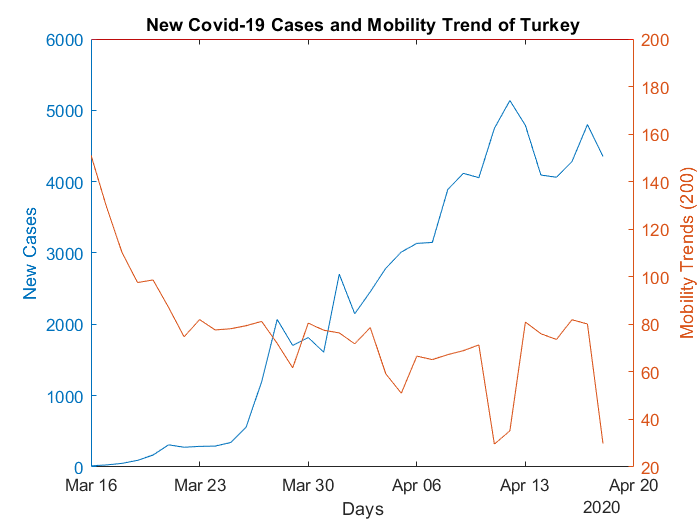

% March 16 to April 18 Turkey
% Mobility trend is 200 in January 13 (Driving + Walking)
figure(1)
turkeyApple= sum(apple{139:140,end-42:end-9});
turkeyNewCases= Covid19.cases(12718:-1:12685)';
turkeyDays=Covid19.dateRep(12718:-1:12685)';
yyaxis left
plot(turkeyDays,turkeyNewCases);
ylabel('New Cases')
yyaxis right
plot(turkeyDays,turkeyApple)
ylabel('Mobility Trends (200)');
xlabel('Days');
yline(200,'r');
title('New Covid-19 Cases and Mobility Trend of Turkey');

Mobility trend is 200 in January 13 (Driving + Walking). We observe a continuous increase in total case from March 16 to April 18. As we can see in the figure mobility trend is always under 200 so we can say that there is no time lag for Turkey.

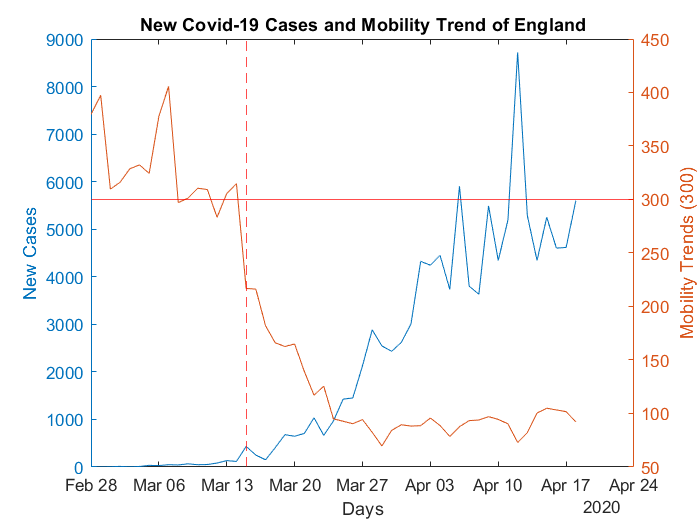

% March 1 to April 18 England
% Mobility trend is 300 in January 13 (Driving + Walking + Transit)
figure(2)
englandApple= sum(apple{141:143,end-59:end-9});
englandNewCases= Covid19.cases(13014:-1:12964)';
englandDays= Covid19.dateRep(13014:-1:12964)';
yyaxis left
plot(englandDays,englandNewCases');
ylabel('New Cases');
yyaxis right
plot(englandDays,englandApple)
ylabel('Mobility Trends (300)');
xlabel('Days');
yline(300,'r');
xline(englandDays(17),'--r');
title('New Covid-19 Cases and Mobility Trend of England');

Mobility trend is 300 in January 13 (Driving + Walking + Transit). We observe a continuous increase in total case from February 28 to April 18. As we can see in the figure mobility trend is under 300 in March 15 and continuous to keep lower than 300 so we can say that there is time lag for England from February 28 to March 15.

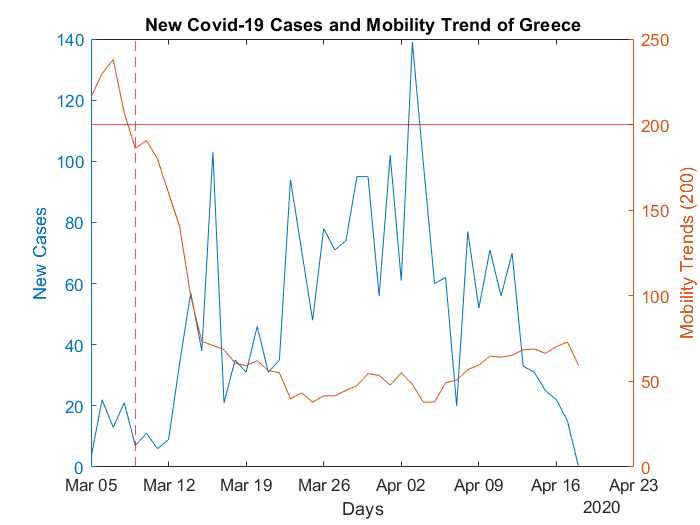

% March 5 to April 18 Greece
% Mobility trend is 200 in January 13 (Driving + Walking)
figure(3)
greeceApple= sum(apple{50:51,end-53:end-9});
greeceNewCases= Covid19.cases(5110:-1:5066)';
greeceDays= Covid19.dateRep(5110:-1:5066)';
yyaxis left
plot(greeceDays,greeceNewCases')
ylabel('New Cases')
yyaxis right
plot(greeceDays,greeceApple)
ylabel('Mobility Trends (200)');
xlabel('Days');
yline(200,'r');
xline(greeceDays(5),'--r');
title('New Covid-19 Cases and Mobility Trend of Greece')

Mobility trend is 200 in January 13 (Driving + Walking). We observe a continuous increase in total case from March 5 to April 18. As we can see in the figure mobility trend is under 200 in March 9 and continuous to keep lower than 200 so we can say that there is time lag for Greece from March 5 to March 9.

**c)** **Is there any positive or negative effect of the curfew declared on 10th April Friday for TURKEY**

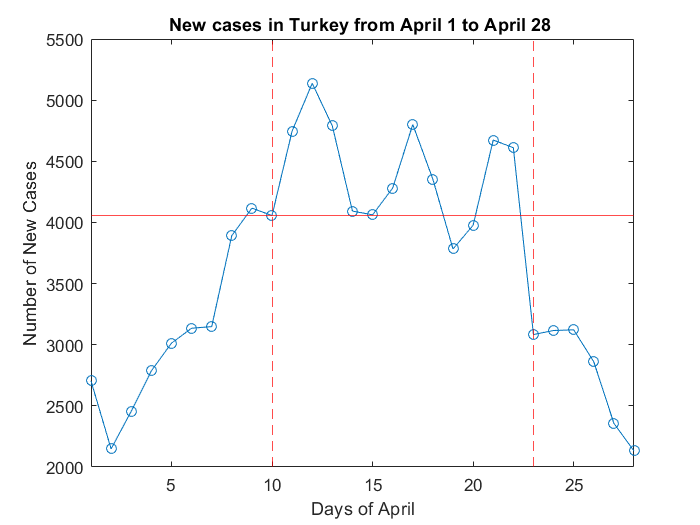

% New cases in Turkey from April 1 to April 28 
figure(4)
turkeyNewCasesApril=Covid19.cases(12702:-1:12675)';
days=1:28;
plot(days,turkeyNewCasesApril,'-o')
xlabel('Days of April')
yline(Covid19.cases(12693),'r');
xline(10,'--r');
xline(23,'--r');
xlim([1 28])
ylabel('Number of New Cases')
title('New cases in Turkey from April 1 to April 28 ')

I think curfew affects positively because symtomps appear in 12 - 14 days, as we can see in the figure, after 13 days from curfew(April 23) there is a huge amount of decrease of new cases and continuous to decrease.

**d) Which days are the milestones (good or bad) for ENGLAND and TURKEY and why? **

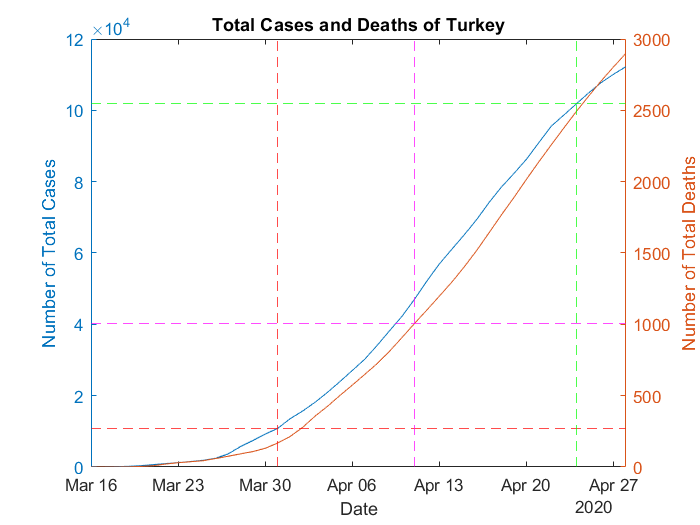

% Finding total Covid-19 Cases and Deaths of Turkey
% From March 16 to April 28
totalCasesPerDayTurkey = zeros(1,44);
totalDeathsPerDayTurkey= zeros(1,44);
for i=1:44
    if i==1
        totalCasesPerDayTurkey(i) = Covid19.cases(12718);
        totalDeathsPerDayTurkey(i)= Covid19.deaths(12718);
    end
    if i>1
        totalCasesPerDayTurkey(i) = totalCasesPerDayTurkey(i-1) + Covid19.cases(12719-i);
        totalDeathsPerDayTurkey(i) = totalDeathsPerDayTurkey(i-1)+ Covid19.deaths(12719-i);
    end
end
figure(5)
daysTurkey=Covid19.dateRep(12718:-1:12675);
yyaxis left
plot(daysTurkey',totalCasesPerDayTurkey)
ylabel('Number of Total Cases');
xlabel('Date');
title('Total Cases and Deaths of Turkey')
% March 31 - 10k+ case
xline(daysTurkey(16),'--r');
yline(totalCasesPerDayTurkey(16),'--r');
% April 24 - 100k+ case
xline(daysTurkey(40),'--g');
yline(totalCasesPerDayTurkey(40),'--g');

yyaxis right
plot(daysTurkey,totalDeathsPerDayTurkey)
ylabel('Number of Total Deaths');
% April 11 - 1k+ death 
xline(daysTurkey(27),'--m');
yline(totalDeathsPerDayTurkey(27),'--m');
xlim([daysTurkey(1) daysTurkey(44)])

March 31, April 11 and April 24 is ones of the milestones for Turkey. In March 31 number of total cases reached 10000 pointed with red dashed lines in figure, in April 11 number of total deaths reached 1000 pointed with magenta dashed lines and in April 24 number of total cases reached 100000 pointed with green dashed lines in figure.

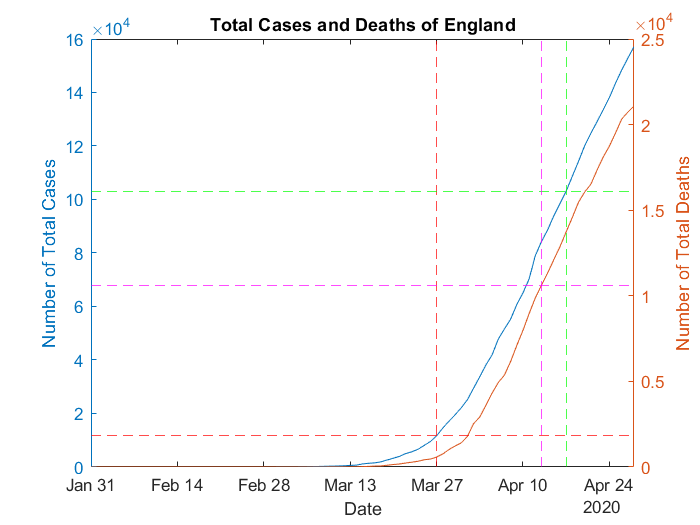

% Finding total Covid-19 Cases and Deaths of England 
% From January 31 to April 28
totalCasesPerDayEngland = zeros(1,89);
totalDeathsPerDayEngland= zeros(1,89);
for i=1:89
    if i==1
        totalCasesPerDayEngland(i) = Covid19.cases(13042);
        totalDeathsPerDayEngland(i)= Covid19.deaths(13042);
    end
    if i>1
        totalCasesPerDayEngland(i) = totalCasesPerDayEngland(i-1) + Covid19.cases(13043-i);
        totalDeathsPerDayEngland(i) = totalDeathsPerDayEngland(i-1)+ Covid19.deaths(13043-i);
    end
end
figure(6)
daysEngland=Covid19.dateRep(13042:-1:12954);
yyaxis left
plot(daysEngland',totalCasesPerDayEngland)
ylabel('Number of Total Cases');
xlabel('Date');
title('Total Cases and Deaths of England')
% March 27 - 10k+ case
xline(daysEngland(57),'--r');
yline(totalCasesPerDayEngland(57),'--r');
% April 17 - 100k+ case
xline(daysEngland(78),'--g');
yline(totalCasesPerDayEngland(78),'--g');

yyaxis right
plot(daysEngland,totalDeathsPerDayEngland)
ylabel('Number of Total Deaths');
% April 13 - 10k+ death 
xline(daysEngland(74),'--m');
yline(totalDeathsPerDayEngland(74),'--m');
xlim([daysEngland(1) daysEngland(89)])

March 27, April 13 and April 17 is ones of the milestones for England. In March 27 number of total cases reached 10000 pointed with red dashed lines in figure, in April 13 number of total deaths reached 10000 pointed with magenta dashed lines and in April 17 number of total cases reached 100000 pointed with green dashed lines in figure.